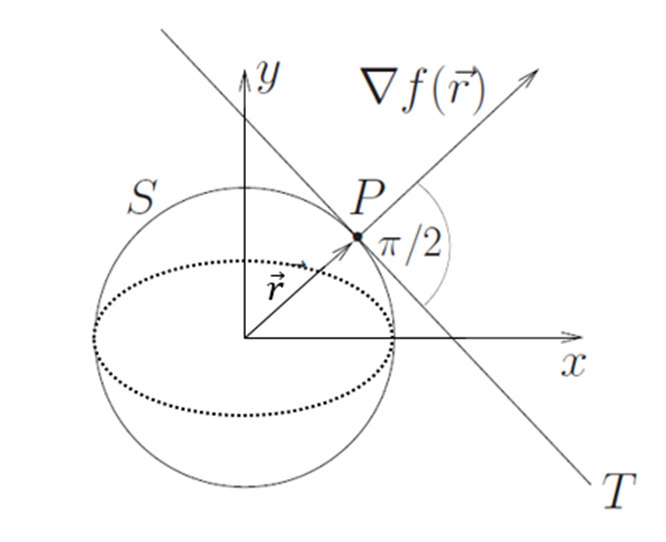

% Define the sphere parameters
R = 1; % Radius of the sphere
theta = linspace(0, 2*pi, 100); % Angle for the circle (longitude)
phi = pi/4; % Fixed latitude for simplicity in visualization

% Create figure
figure;
hold on;
axis equal;
grid on;
xlabel('X');
ylabel('Y');
zlabel('Z');
title('Sphere with Normal and Tangent Vector and Dynamic Labels');

% Plot the sphere
[x, y, z] = sphere;
hSurf = surf(x*R, y*R, z*R, 'FaceAlpha', 0.5, 'EdgeColor', 'none'); % Handle for the sphere

% Animate the normal and tangent vectors with labels
for i = 1:length(theta)
    % Coordinates of P on the sphere
    xP = R * cos(phi) * cos(theta(i));
    yP = R * cos(phi) * sin(theta(i));
    zP = R * sin(phi);
    
    % Normal vector (normalized)
    normalVec = [2*xP, 2*yP, 2*zP] / 2; % Correct scaling
    
    % Tangent vector at P
    tangentVec = [-normalVec(2), normalVec(1), 0]; % Example tangent vector
    
    % Clear previous vectors and text to animate
    cla;
    
    % Re-plot the sphere
    surf(x*R, y*R, z*R, 'FaceAlpha', 0.5, 'EdgeColor', 'none');
    
    % Plot normal vector
    quiver3(xP, yP, zP, normalVec(1), normalVec(2), normalVec(3), 'r', 'LineWidth', 2, 'MaxHeadSize', 0.5);
    
    % Plot tangent vector
    quiver3(xP, yP, zP, tangentVec(1), tangentVec(2), tangentVec(3), 'g', 'LineWidth', 2, 'MaxHeadSize', 0.5);
    
    % Plot point P
    plot3(xP, yP, zP, 'ko', 'MarkerSize', 8, 'MarkerFaceColor', 'k');
    
    % Add dynamic labels
    text(xP, yP, zP + 0.1, sprintf('P(%.2f, %.2f, %.2f)', xP, yP, zP));
    text(xP + normalVec(1), yP + normalVec(2), zP + normalVec(3), sprintf('N(%.2f, %.2f, %.2f)', normalVec));
    text(xP + tangentVec(1), yP + tangentVec(2), zP + tangentVec(3), sprintf('T(%.2f, %.2f, %.2f)', tangentVec));
    
    % Adjust the view and limits
    view(3);
    axis equal;
    xlim([-R R]);
    ylim([-R R]);
    zlim([-R R]);
    
    drawnow;
    
    % Pause to control animation speed
    pause(0.05);
end

hold off;


% Define parameters for the helical path on the cone
t = linspace(0, 4*pi, 100); % Parameter t for the path
r = t; % Radius from the cone's center increases with t
z = r; % Height on the cone increases with r (to stay on the cone surface)
x = r .* cos(t);
y = r .* sin(t);

% Cone parameters for plotting
[X, Y, Z] = cylinder(0:0.1:1, 100);
Z = Z * max(z); % Scale the height of the cone to match the path
X = X * max(r); % Adjust the radius
Y = Y * max(r); % Adjust the radius

% Create figure
figure;
hold on;
axis equal;
grid on;
xlabel('X');
ylabel('Y');
zlabel('Z');
title('Cone with Normal Vector and Unit Surface Normal Vector');

% Plot the cone
hCone = surf(X, Y, Z, 'FaceAlpha', 0.5, 'EdgeColor', 'none');

% Animate the point P along the cone with the normal and unit normal vectors
for i = 1:length(t)
    % Normal vector at P
    normalVec = [8*x(i), 8*y(i), -2*z(i)];
    % Unit normal vector at P
    unitNormalVec = normalVec / norm(normalVec);
    
    % Clear previous vectors to animate
    delete(findall(gcf,'type','annotation'));
    cla;
    
    % Re-plot the cone
    surf(X, Y, Z, 'FaceAlpha', 0.5, 'EdgeColor', 'none');
    
    % Plot point P
    plot3(x(i), y(i), z(i), 'ko', 'MarkerSize', 8, 'MarkerFaceColor', 'k');
    
    % Plot normal vector
    quiver3(x(i), y(i), z(i), normalVec(1), normalVec(2), normalVec(3), 'r', 'LineWidth', 2, 'MaxHeadSize', 0.5);
    
    % Plot unit normal vector
    quiver3(x(i), y(i), z(i), unitNormalVec(1), unitNormalVec(2), unitNormalVec(3), 'g', 'LineWidth', 2, 'MaxHeadSize', 0.5);
    
    % Dynamic labels for P, normal, and unit normal vectors
    text(x(i), y(i), z(i) + 1, sprintf('P(%.2f, %.2f, %.2f)', x(i), y(i), z(i)));
    text(x(i) + normalVec(1), y(i) + normalVec(2), z(i) + normalVec(3), 'Normal', 'Color', 'red');
    text(x(i) + unitNormalVec(1), y(i) + unitNormalVec(2), z(i) + unitNormalVec(3), 'Unit Normal', 'Color', 'green');
    
    % Adjust the view and limits
    view(3);
    axis equal;
    xlim([-max(r) max(r)]);
    ylim([-max(r) max(r)]);
    zlim([0 max(z)]);
    
    drawnow;
    
    % Pause to control animation speed
    pause(0.05);
end

hold off;


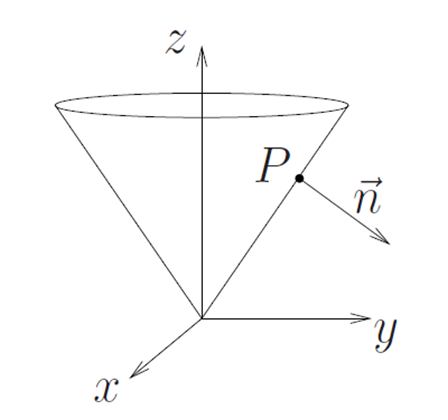

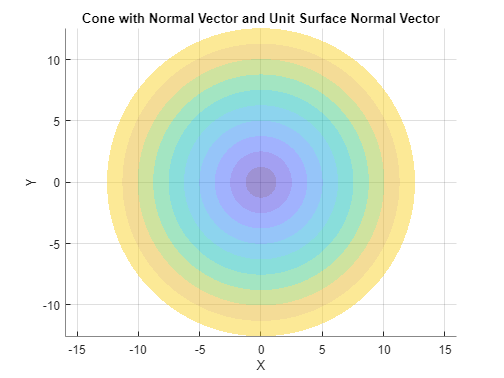

clear

% Define parameters for the helical path on the cone
t = linspace(0, 4*pi, 100); % Parameter t for the path
r = t; % Radius from the cone's center increases with t
z = r; % Height on the cone increases with r (to stay on the cone surface)
x = r .* cos(t);
y = r .* sin(t);

% Cone parameters for plotting
[X, Y, Z] = cylinder(0:0.1:1, 100);
Z = Z * max(z); % Scale the height of the cone to match the path
X = X * max(r); % Adjust the radius
Y = Y * max(r); % Adjust the radius

% Create figure
figure;
hold on;
axis equal;
grid on;
xlabel('X');
ylabel('Y');
zlabel('Z');
title('Cone with Normal Vector and Unit Surface Normal Vector');

% Plot the cone
hCone = surf(X, Y, Z, 'FaceAlpha', 0.5, 'EdgeColor', 'none');

% Animate the point P along the cone with the normal and unit normal vectors
for i = 1:length(t)
    % Normal vector at P
    normalVec = [8*x(i), 8*y(i), -2*z(i)];
    % Unit normal vector at P
    unitNormalVec = normalVec / norm(normalVec);
    
    % Clear previous vectors to animate
    delete(findall(gcf,'type','annotation'));
    cla;
    
    % Re-plot the cone
    surf(X, Y, Z, 'FaceAlpha', 0.5, 'EdgeColor', 'none');
    
    % Plot point P
    plot3(x(i), y(i), z(i), 'ko', 'MarkerSize', 8, 'MarkerFaceColor', 'k');
    
    % Plot normal vector
    quiver3(x(i), y(i), z(i), normalVec(1), normalVec(2), normalVec(3), 'r', 'LineWidth', 2, 'MaxHeadSize', 0.5);
    
    % Plot unit normal vector
    quiver3(x(i), y(i), z(i), unitNormalVec(1), unitNormalVec(2), unitNormalVec(3), 'g', 'LineWidth', 2, 'MaxHeadSize', 0.5);
    
    % Dynamic labels for P, normal, and unit normal vectors
    text(x(i), y(i), z(i) + 1, sprintf('P(%.2f, %.2f, %.2f)', x(i), y(i), z(i)));
    text(x(i) + normalVec(1), y(i) + normalVec(2), z(i) + normalVec(3), 'Normal', 'Color', 'red');
    text(x(i) + unitNormalVec(1), y(i) + unitNormalVec(2), z(i) + unitNormalVec(3), 'Unit Normal', 'Color', 'green');
    
    % Adjust the view and limits
    view(3);
    axis equal;
    xlim([-max(r) max(r)]);
    ylim([-max(r) max(r)]);
    zlim([0 max(z)]);
    
    drawnow;
    
    % Pause to control animation speed
    pause(0.05);
end

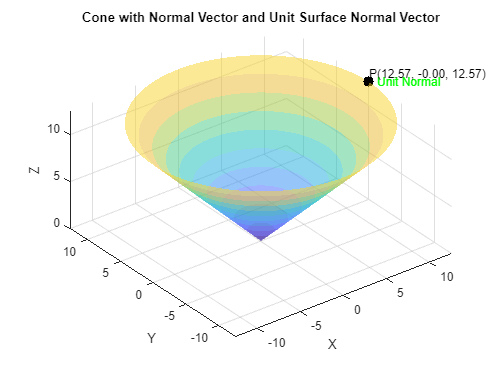


hold off;

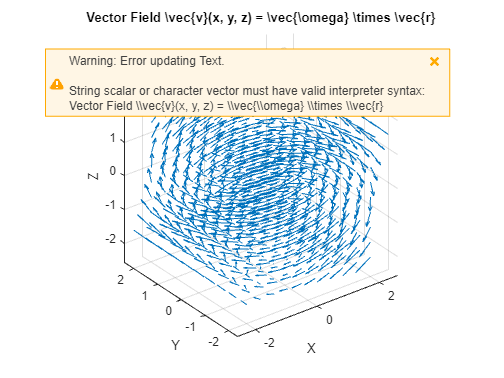

clear

% Define the fixed vector omega
omega = [1, 2, 1]; % Example values for omega

% Grid of points in 3D space
[x, y, z] = meshgrid(linspace(-2, 2, 10), linspace(-2, 2, 10), linspace(-2, 2, 10));

% Vector field v(x, y, z) calculation
vx = omega(2)*z - omega(3)*y;
vy = omega(3)*x - omega(1)*z;
vz = omega(1)*y - omega(2)*x;

% Create figure for the vector field
figure;
quiver3(x, y, z, vx, vy, vz, 'AutoScaleFactor', 2);
axis equal;
grid on;
xlabel('X');
ylabel('Y');
zlabel('Z');
title('Vector Field \vec{v}(x, y, z) = \vec{\omega} \times \vec{r}');


% Divergence of the vector field
divV = divergence(x, y, z, vx, vy, vz);

% Since divV is expected to be zero everywhere, we can illustrate this by
% displaying the maximum absolute value of the divergence to show it's close to zero.
maxDivV = max(abs(divV(:)));
disp(['Maximum absolute divergence of the vector field: ', num2str(maxDivV)]);

Maximum absolute divergence of the vector field: 0


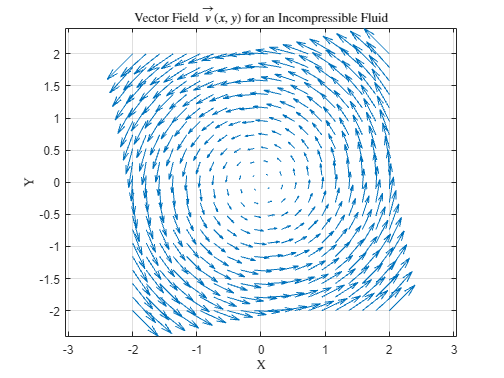

clear

% Define a 2D grid
[x, y] = meshgrid(linspace(-2, 2, 20), linspace(-2, 2, 20));

% Define a simple velocity field (vx, vy) for an incompressible fluid
% Example: Circular motion around the origin
vx = -y;
vy = x;

% Calculate the divergence of the velocity field
divV = divergence(x, y, vx, vy);

% Create figure for the velocity field
figure;
quiver(x, y, vx, vy, 'AutoScaleFactor', 2);
axis equal;
grid on;
xlabel('X', 'Interpreter', 'latex');
ylabel('Y', 'Interpreter', 'latex');
title('Vector Field $\vec{v}(x, y)$ for an Incompressible Fluid', 'Interpreter', 'latex');


% Since the divergence is zero everywhere, a contour plot might not be informative.
% However, you can still display it if you'd like to visually confirm its uniformity.
figure;
contourf(x, y, divV, 20); % This might not show variations due to constant divergence

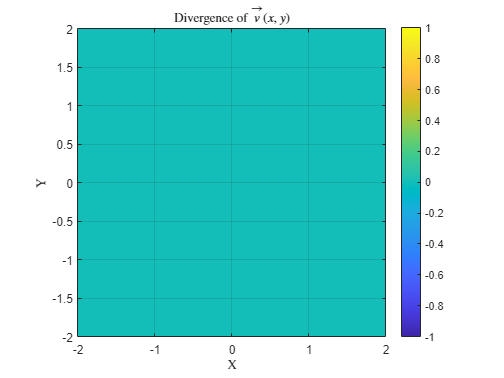

colorbar;
axis equal;
grid on;
xlabel('X', 'Interpreter', 'latex');
ylabel('Y', 'Interpreter', 'latex');
title('Divergence of $\vec{v}(x, y)$', 'Interpreter', 'latex');